# Template of Manipulator Short project: Skull tumor surgery

Authors: **Adrian Cristian Crisan**

I spect: 1) Pdf file, 2) Videos demostrating your successful task and your mlx file.

Notes. For better undestanding you can split the videos in the meaninful task.

Remember use the options of serial/link plot: 

'workspace' for centering in the surgery task

'zoom' ...  nice puma ratio aspect

'trail'  .. to see the trajectory

etc..

See all at:

>> help SerialLink/plot

## The Robotic environment (10%)

Use: 'c = uisetcolor' to chose color

### Operating table.

 It can be raised, lowered, and tilted in any direction, and an  auxiliary table for the tools. Define: vertices and Faces and use  'patch'  functions to model it. See help patch to find and example

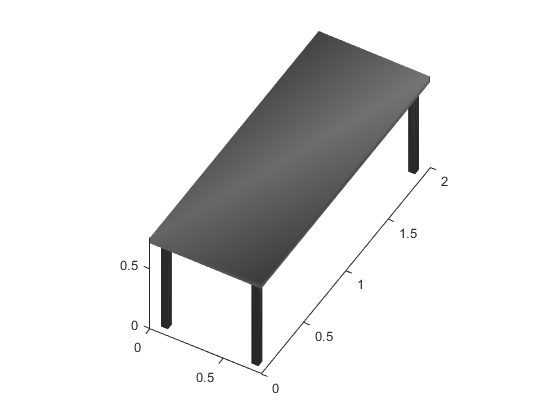

clear;
close all;
clf

gurney = load("Gurney.mat");

% Scale Gurney
gurney_vertices = rescale(gurney.Gurney_vertices, 0, 2);
zmaxG = max(gurney_vertices(:, 3));
xmaxG = max(gurney_vertices(:, 1));

figure
patch('Vertices', gurney_vertices, 'Faces', gurney.Gurney_faces, ...
    'FaceColor', [0.52, 0.52, 0.52], ...
    'EdgeColor', 'none', ...
    'FaceLighting', 'gouraud', ...
    'AmbientStrength', 0.15);

% Add a camera light, and tone down the specular highlighting
camlight('headlight');
material('dull');

view(30,45)
axis equal

### 3D model of a human body 

Situate the human model on the operating table. You will have to scale it.

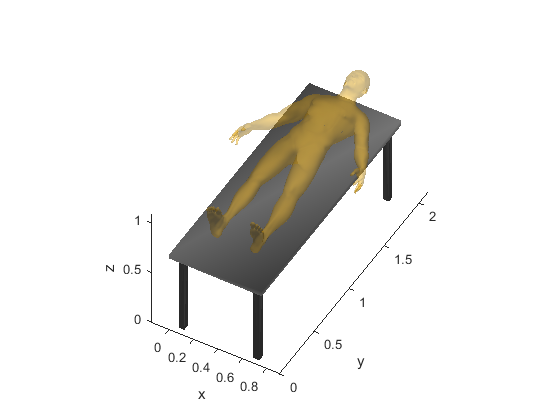

human = load("F_V_Human_Body.mat");

% Scale human
human_scale = 0.09;                          
human_vertices = human_scale .* human.V';   

% Transformation of the position of the human
zminH = min(human_vertices(3, :));
T_Body_Ini = transl(xmaxG/2, 0.27, zmaxG - zminH);   
human_vertices = (T_Body_Ini * [human_vertices; ones(1, length(human.V))])';

% Display the human
patch('Vertices', human_vertices(:, 1:3), 'Faces', human.F, ...
    'FaceColor', [0.9290, 0.6940, 0.1250], ...
    'FaceAlpha', 0.3, ...
    'EdgeColor', 'none', ...
    'FaceLighting', 'gouraud', ...
    'AmbientStrength', 0.15);
% Add effect to the faces
material('dull');

zlabel('z'); ylabel('y'); xlabel('x');
view(30,45)
axis equal

### Human skull model

Embedded in the head of the human. You will have to scale it and find the the transformation by hand.

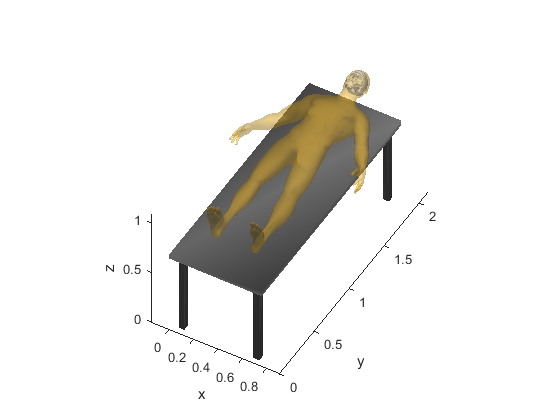

skull = load("F_V_N_Skull.mat");

% Scale Skull
skull_scale = 0.0069;
skull_vertices = skull_scale .* skull.Ve';

% Transformation of the position of the skull
T_Skull_Ini = transl(xmaxG/2, 1.917, 0.917) * trotx(-83 * pi/180);
skull_vertices = (T_Skull_Ini * [skull_vertices; ones(1, length(skull.Ve))])';

% Display Skull
patch('Vertices', skull_vertices(:, 1:3), 'Faces', skull.Fa, ...
    'FaceColor', 'w', ...
    'FaceAlpha', 0.5, ...
    'EdgeColor', 'none', ...
    'FaceLighting', 'gouraud', ...
    'AmbientStrength', 0.15);
% Add effect to the faces
material('dull');

view(30,45)
axis equal

### Dicom image vs Image reference frame

Use the Box as a container of the skull. You can infer the Image Reference Frame {I}

See: Help_Image_RF_Containig_Box.fig and 6_Plot_Box_Cone.mlx to inspire yourselt about Image Reference Frame

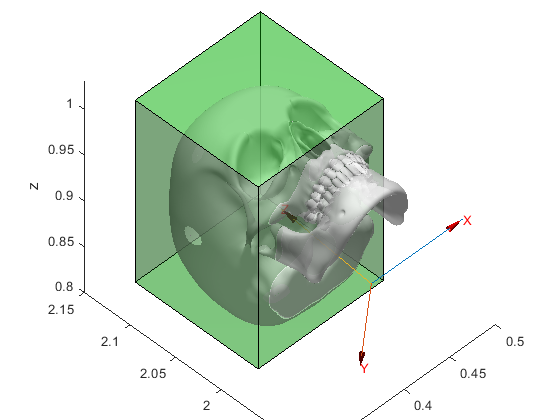

figure
% Display Skull
patch('Vertices', skull_vertices(:, 1:3), 'Faces', skull.Fa, ...
    'FaceColor', 'w', ...
    'FaceAlpha', 0.6, ...
    'EdgeColor', 'none', ...
    'FaceLighting', 'gouraud', ...
    'AmbientStrength', 0.15);

% Add a camera light, and tone down the specular highlighting
camlight('headlight');
material('dull');

% Gets the positions to create the box that contain the skull
xmaxS = max(skull_vertices(:, 1));
xminS = min(skull_vertices(:, 1));
ymaxS = max(skull_vertices(:, 2));
yminS = min(skull_vertices(:, 2));
yminS = yminS + (ymaxS - yminS) / 3;
zmaxS = max(skull_vertices(:, 3));
zminS = min(skull_vertices(:, 3));

% Creates the box
cube_vertices = [
    xminS ymaxS zminS;
    xmaxS ymaxS zminS;
    xmaxS ymaxS zmaxS;
    xminS ymaxS zmaxS;
    
    xminS yminS zminS;
    xmaxS yminS zminS;
    xmaxS yminS zmaxS;
    xminS yminS zmaxS
];
cube_faces = [
    1 2 6 5;
    2 3 7 6;
    3 4 8 7;
    4 1 5 8;
    1 2 3 4;
    5 6 7 8
];

hold on
% Display the box
patch('Vertices', cube_vertices, 'Faces', cube_faces, ...
    'FaceVertexCData', hsv(6), ...
    'FaceColor', 'g', ...
    'FaceAlpha',0.3);

% Display the Skull Reference Frame
trplot(T_Skull_Ini, 'length', 0.1, 'arrow', 'color', 'r');

zlabel('z'); ylabel('y'); xlabel('x');
axis equal
view(-45,45)

### Fiducials wrt {I}

Use the Dicom images to register the fiducial relative to Image Reference Frame {I}.

Think about how many reference frames are envolved.

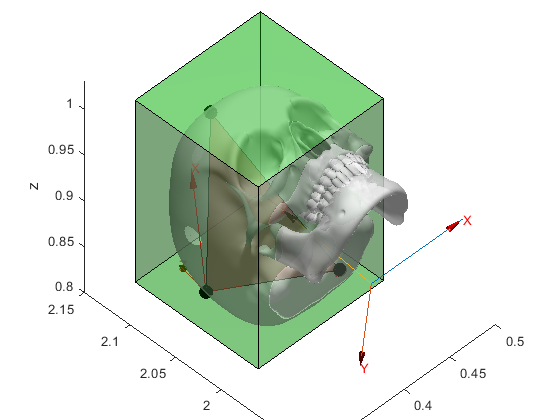

% We use https://www.imaios.com/en/Imaios-Dicom-Viewer#! and the Dicom images to estimate the
% Fiducials positions
hold on

fiducial_1 = T_Skull_Ini * [0.0416, 0.0766, 0.067, 1]';
fiducial_2 = T_Skull_Ini * [-0.0497, 0.082, 0.1219, 1]';
fiducial_3 = T_Skull_Ini * [0.0071, -0.0305, 0.188, 1]';

% Displays the fiducials
[X,Y,Z] = sphere;
r=0.005;        % 5 mm
surf(X*r + fiducial_1(1), Y*r + fiducial_1(2), Z*r + fiducial_1(3), 'FaceColor', [1 0 0])
surf(X*r + fiducial_2(1), Y*r + fiducial_2(2), Z*r + fiducial_2(3), 'FaceColor', [1 0 0])
surf(X*r + fiducial_3(1), Y*r + fiducial_3(2), Z*r + fiducial_3(3), 'FaceColor', [1 0 0])
triangle = [fiducial_1(1:3), fiducial_2(1:3), fiducial_3(1:3)];
fill3(triangle(1, :), triangle(2, :), triangle(3, :)', 'r', 'FaceAlpha', 0.5)

% Estimates the position between the fiducials and the skull
AB = (triangle(1:3,1) - triangle(1:3,2)) / norm(triangle(1:3,1) - triangle(1:3,2)); % Vector pointing A 
CB = (triangle(1:3,3) - triangle(1:3,2)) / norm(triangle(1:3,2) - triangle(1:3,3)); % Vector pointing C
Z_B = cross(CB, AB) / norm(cross(CB, AB));                                          % Perpendicular to BA & CB equivalent to â; Z point up
O_B_A = oa2r(AB, Z_B);                                                              % AB is the orientation vector (y axis ô) and Z_B is the aproach axis (z axis â). The result ^n is in x axis
T_Fiducials_Ini = [O_B_A fiducial_2(1:3); 0 0 0 1];
T_Skull_Fiducials = inv(T_Fiducials_Ini) * T_Skull_Ini;

trplot(T_Fiducials_Ini, 'length', 0.1, 'arrow', 'color', 'r');

### Tumor points wrt {I}

Use the Dicom images to get the points of the outer perimeter of the tumor relative to Image Reference Frame {I}.

You can simplify the tumor information by defining the center of mass and estimate an equivalent diameter.

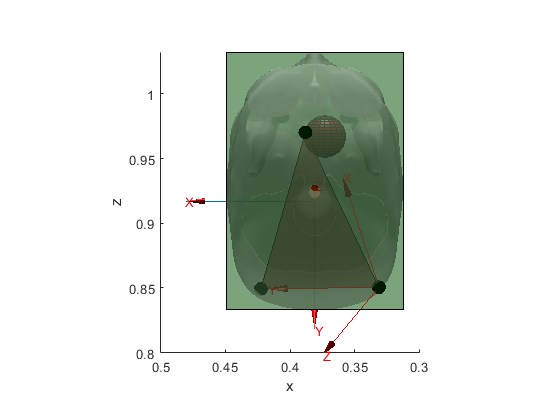

% We use https://www.imaios.com/en/Imaios-Dicom-Viewer#! and the Dicom images to get and
% Gets the tumor size and position
hold on 
T_Tumor_Skull = [-0.008, -0.030, 0.076*1.4 + 0.06, 1];
tumor = T_Skull_Ini * T_Tumor_Skull';

% Displays the tumor
[X,Y,Z] = sphere;
r = 0.016;          % 16mm radius tumor 
surf(X*r + tumor(1), Y*r + tumor(2), Z*r + tumor(3),'FaceColor',[1 0 0])
view(-180,0)

## *First approach (10%)  *

*Asume that the ZX plane of the Robot is aligned with the plane of symmetry of the human body.*

### Robot manipulator

Consider  the best position of manipulator to be nearby the operating table to warranty that the head is in the reachable work space. Use a Puma 560. Use p560.teach to play.

Use: p560.base & p560.tool to locate the Puma and add the tools.

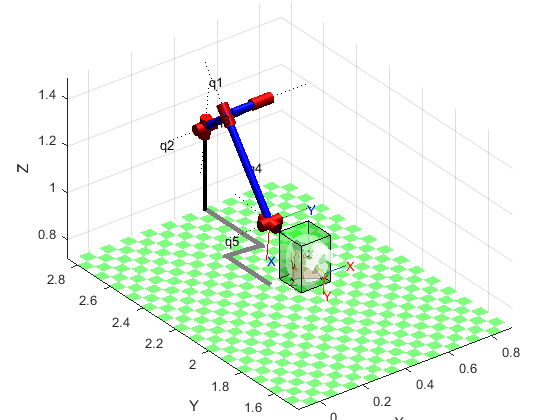

% Displays the robot (without any tool)
hold on
mdl_puma560
xbase = T_Tumor_Skull(1) + p560.links(3).d;
zbase = T_Tumor_Skull(3) + sqrt(2) * p560.links(2).a + 0.15;
ybase = T_Tumor_Skull(2) - r;

p560.base = T_Skull_Ini * transl(xbase, ybase, zbase) * trotz(-pi/2) * troty(pi/2);
workspaceX = [T_Skull_Ini(1, 4) - 0.5, T_Skull_Ini(1, 4) + 0.5];
workspaceY = [T_Skull_Ini(2, 4) - zbase/2, T_Skull_Ini(2, 4) + zbase];
workspaceZ = [T_Skull_Ini(3, 4) - 0.2, T_Skull_Ini(3, 4) + 1];
p560.plot(qn, 'zoom', 2.5, 'workspace', [workspaceX, workspaceY, workspaceZ], 'jaxes');
axis equal

### Transformations

Enumerate the transformation you will need.

% Del reference frame inicial al body
T_Body_Ini;
% Del reference frame del cráneo al body
T_Body_Skull = inv(T_Skull_Ini) * T_Body_Ini;
% Del reference frame inicial al de la base del robot
T_R_I = T_Skull_Ini * transl(xbase, ybase, zbase) * trotz(-pi/2) * troty(pi/2);
% Del reference frame del craneo al inicial
T_Skull_Ini;
% Del reference frame del craneo al del robot
T_R_S = inv(T_Skull_Ini) * T_R_I;
% Del reference frame inicial al del tumor
T_T_I = transl(tumor(1), tumor(2), tumor(3));

### Reference Frames

Display all necessary reference frame. Use best scale to see it.

- {U} Univers [0 0 0]

- {R} Robot

- {I} Image

- {Tb} Table_body

- {EE} End Efector

- others

- ...

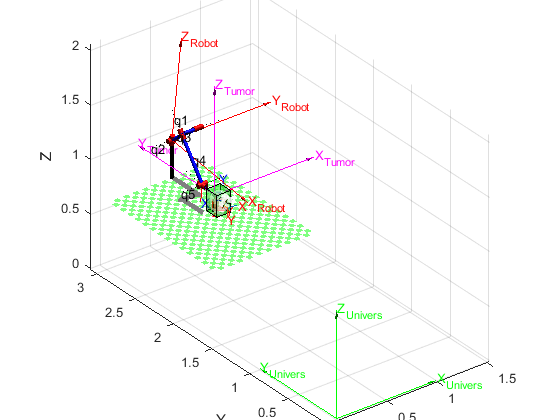

% Reference Frame of the Univers and the Table
trplot(eye(4), 'frame', 'Univers', 'arrow', 'color', 'g');
% Reference Frame of the Robot
trplot(T_R_I, 'frame', 'Robot', 'arrow', 'color', 'r');
% Reference Frame of the Tumor
trplot(T_T_I, 'frame', 'Tumor', 'arrow', 'color', 'm');
xlim([-0.10 1.52])
ylim([-0.01 3.08])
zlim([-0.01 2.07])

% Reference Frame of the tool (already plotted)

### Tumor points in Robot Frame.

T_T_R = inv(T_R_I) * T_T_I;

## Surgery (40%)

### Biospy

Prepare a script that perform a biopsy. Zoom in the scene and record a video with the best view.

Use a tool that has the following Transformation: transl(0.05 0 0.25)

Let us see the 'trail' option of plot to visualize the trajectory.

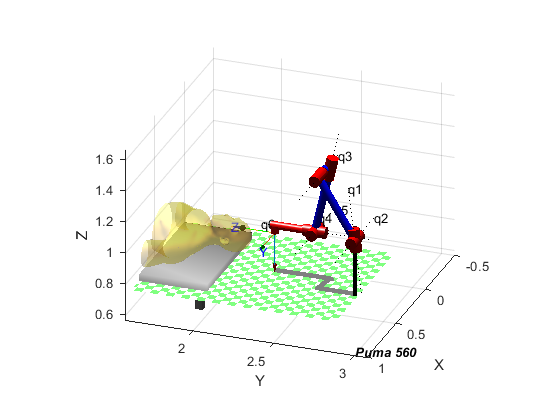

close all

figure
% Display Gurney
patch('Vertices', gurney_vertices, 'Faces', gurney.Gurney_faces, ...
    'FaceColor', [0.52, 0.52, 0.52], ...
    'EdgeColor', 'none', ...
    'FaceLighting', 'gouraud', ...
    'AmbientStrength', 0.15);

% Add a camera light, and tone down the specular highlighting
camlight('headlight');
material('dull');

xlim([tumor(1) - 0.4, tumor(1) + 0.4])
ylim([tumor(2) - 0.5, tumor(2) + 1])
zlim([tumor(3) - 0.4, tumor(3) + 0.7])

% Display Body
patch('Vertices', human_vertices(:, 1:3), 'Faces', human.F, ...
    'FaceColor', [0.9290, 0.6940, 0.1250], ...
    'FaceAlpha', 0.3, ...
    'EdgeColor', 'none', ...
    'FaceLighting', 'gouraud', ...
    'AmbientStrength', 0.15);
material('dull');

axis equal
hold on
% Display Tumour
surf(X*r + tumor(1), Y*r + tumor(2), Z*r + tumor(3),'FaceColor',[1 0 0])

% Transformation to move the tool appropriately
T_tool = troty(pi/2) * trotx(pi/2);

n = 200;
% Go inside the skull
for i = 1:n
    Biopsy_Pose(:, :, i) = transl(tumor(1), tumor(2) +  0.2 * ((n - i)/n), tumor(3)) * T_tool;
end

% Stay inside the skull
for i = 1:n/4
    Biopsy_Pose(:, :, i+n) = transl(tumor(1), tumor(2), tumor(3)) * T_tool;
end

% Go outside the skull
for i = 1:n
    Biopsy_Pose(:, :, i+n+n/4) = transl(tumor(1), tumor(2) + 0.2 * (1 - ((n - i)/n)), tumor(3)) * T_tool;
end

% Display Robot
mdl_puma560
p560.tool = transl(0.05, 0, 0.25);
p560.base = T_Skull_Ini * transl(xbase, ybase, zbase) * trotz(-pi/2) * troty(pi/2);
Q1 = p560.ikine6s(Biopsy_Pose, 'run');
p560.plot(Q1, 'view', [110 25], 'workspace', [workspaceX, workspaceY, workspaceZ], 'trail', {'color', 'g'}, 'jaxes', 'zoom', 2);

% Creates the video
% p560.plot(Q1, 'view', [110 25], 'workspace', [workspaceX, workspaceY, workspaceZ], 'trail', {'color', 'g'}, 'zoom', 2, 'movie', 'Puma_biopsy_task.mp4');

### Trepanation

Prepare a script that perform trepanation. Zoom in the scene and record a video with the best view.

Use a tool that has the following Transformation: transl(0 0 0.2)

Let us see the 'trail' option of plot to visualize the trajectory. Place a 45º cone on top of the trepanation to better understand. See: 6_Plot_Box_Cone.mlx. You will have to scale it. Play with transparency.

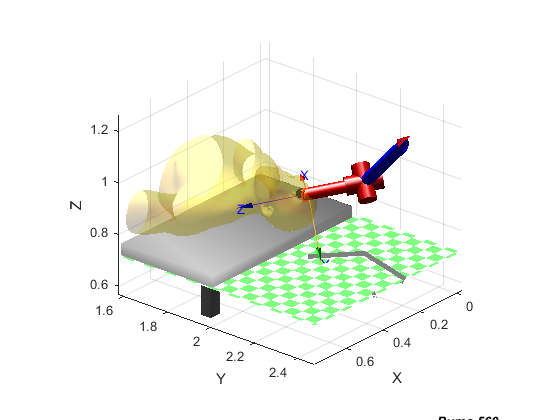

close all

figure
% Display Gurney
patch('Vertices', gurney_vertices, 'Faces', gurney.Gurney_faces, ...
    'FaceColor', [0.52, 0.52, 0.52], ...
    'EdgeColor', 'none', ...
    'FaceLighting', 'gouraud', ...
    'AmbientStrength', 0.15);

% Add a camera light, and tone down the specular highlighting
camlight('headlight');
material('dull');

xlim([tumor(1) - 0.4, tumor(1) + 0.4])
ylim([tumor(2) - 0.5, tumor(2) + 0.4])
zlim([tumor(3) - 0.4, tumor(3) + 0.3])

% Display Body
patch('Vertices', human_vertices(:, 1:3), 'Faces', human.F, ...
    'FaceColor', [0.9290, 0.6940, 0.1250], ...
    'FaceAlpha', 0.3, ...
    'EdgeColor', 'none', ...
    'FaceLighting', 'gouraud', ...
    'AmbientStrength', 0.15);
material('dull');

% Display Skull
% patch('Vertices', skull_vertices(:, 1:3), 'Faces', skull.Fa, ...
%     'FaceColor', [0.82, 0.82, 0.82], ...
%     'FaceAlpha', 0.6, ...
%     'EdgeColor', 'none', ...
%     'FaceLighting', 'gouraud', ...
%     'AmbientStrength', 0.15);
% material('dull');
% axis equal

hold on
% Display Tumour
surf(X*r + tumor(1), Y*r + tumor(2), Z*r + tumor(3),'FaceColor',[1 0 0])

n = 100;
radius = r;

load('Cone.mat')

% Gets the cone transformation
xminC = min(fvc.vertices(:, 1));
xmaxC = max(fvc.vertices(:, 1));
cone_scale = r/((xmaxC - xminC)/2);
cone_vertices = cone_scale .* fvc.vertices';

cone_pose = transl(tumor(1), ymaxS-0.005, tumor(3)) * trotx(103 * pi/180);   
cone_vertices = (cone_pose * [cone_vertices; ones(1, length(cone_vertices))])';

% Displays the Cone
patch('Vertices', cone_vertices(:, 1:3), 'Faces', fvc.faces, ...
    'FaceVertexCData', hsv(6), ...
    'FaceColor', 'b', ...
    'FaceAlpha', 0.3);

% Display the trepanation perimeter
T_tool = troty(pi/4) * trotx(pi);
Trep_pose = cone_pose * troty(182 * pi/180) * transl(0, 0, -0.001);
for i=1:n
    Trepanation_Pose(:,:,i)= Trep_pose*trotz(2*pi*i/n)*transl(radius-0.001, 0, 0) * T_tool;
end

cir=transl(Trepanation_Pose)';
hold on
plot3(cir(1,:), cir(2,:), cir(3,:),'r','LineWidth',3);

% Display Robot
mdl_puma560
p560.tool = transl(0, 0, 0.2);
p560.base = T_Skull_Ini * transl(xbase, ybase, zbase) * trotz(-pi/2) * troty(pi/2);
Q2 = p560.ikine6s(Trepanation_Pose, 'run');
p560.plot(Q2, 'view', [130 25], 'workspace', [workspaceX, workspaceY, workspaceZ], 'trail', {'color', 'g'}, 'zoom', 2);

% Creates the video
% p560.plot(Q2, 'view', [130 25], 'workspace', [workspaceX, workspaceY, workspaceZ], 'trail', {'color', 'g'}, 'zoom', 2, 'movie', 'Puma_trepanation_task.mp4');

### Tumor burning

Prepare a script that perform tumor burning with the laser.  Zoom in the scene and record a video with the best view.

You ought to think in an algorithm, that in order, fill up the tumor's  equivalent sphere with small burning spheres of 4m diameter.

Use a tool that has the following Transformation: transl(0 0 0.2)

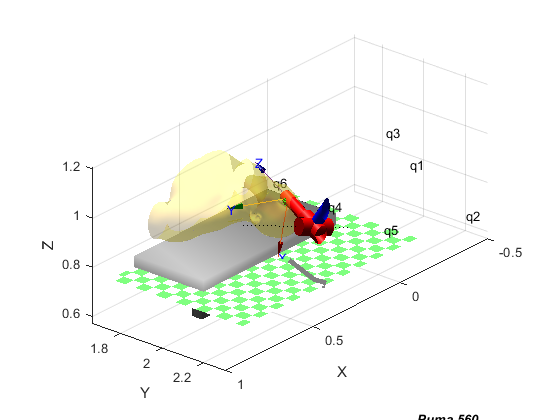

close all

figure
% Display Gurney
patch('Vertices', gurney_vertices, 'Faces', gurney.Gurney_faces, ...
    'FaceColor', [0.52, 0.52, 0.52], ...
    'EdgeColor', 'none', ...
    'FaceLighting', 'gouraud', ...
    'AmbientStrength', 0.15);

% Add a camera light, and tone down the specular highlighting
camlight('headlight');
material('dull');

xlim([0.053 0.692])
ylim([1.667 2.306])
zlim([0.572 1.211])
axis equal

% Display Body
patch('Vertices', human_vertices(:, 1:3), 'Faces', human.F, ...
    'FaceColor', [0.9290, 0.6940, 0.1250], ...
    'FaceAlpha', 0.3, ...
    'EdgeColor', 'none', ...
    'FaceLighting', 'gouraud', ...
    'AmbientStrength', 0.15);
material('dull');
hold on

plot3(cir(1,:), cir(2,:), cir(3,:),'r','LineWidth',3);

% Displays the tumor
[X,Z,Y] = sphere;
r = 0.016;          % 16mm radius tumor 
surf(X*r + tumor(1), Y*r + tumor(2), Z*r + tumor(3), 'FaceColor', [1 0 0], 'FaceAlpha', 0.5)

% Transformation to move the tool appropriately
T_tool = troty(pi/2) * trotx(pi/2);

P_trepanation = [tumor(1), ymaxS-0.005, tumor(3)];

% Get burning points
center = tumor(1:3)';
r_burning = 0.002;
queue = center;
burning_points = center;
visited = center;

adjacent = [     r_burning,          0,          0;
                -r_burning,          0,          0;
                         0,  r_burning,          0;
                         0, -r_burning,          0;
                         0,          0,  r_burning;
                         0,          0, -r_burning];
count = 1;
while isempty(queue) == 0
    act = queue(1, :);
    m = size(queue);
    queue = queue(2:m(1), :);
    
    for k = 1:length(adjacent)
        pos = act + adjacent(k, :);
        m = size(visited);

        xb = pos(1);
        yb = pos(2);
        zb = pos(3);
        
        ca = P_trepanation(2) - yb;
        co1 = P_trepanation(1) - xb;
        h1 = sqrt(co1^2 + ca^2);
        alphaX = asin(co1/h1);

        co2 = P_trepanation(3) - zb;
        h2 = sqrt(co2^2 + ca^2);
        alphaZ = asin(co2/h2);

        dist = sqrt( (P_trepanation(1) - xb)^2 +  (P_trepanation(2) - yb)^2 + (P_trepanation(3) - zb)^2 );
        
        vis = false;
        for t = 1:m(1)
            if visited(t, 1) == pos(1) && visited(t, 2) == pos(2) && visited(t, 3) == pos(3)
                vis = true;
                break;
            end
        end
        
        if ~vis
            distance = sqrt((center(1) - pos(1))^2 + (center(2) - pos(2))^2 + (center(3) - pos(3))^2);
            if distance <= r
                queue = [queue; pos];
                burning_points = [burning_points; pos];
                visited = [visited; pos];
                Burning_Pose(:, :, count) = transl(P_trepanation) * T_tool * troty(-alphaX) * trotx(alphaZ) * transl(0, 0, dist);
                count = count + 1;
            end
        end
    end
end

% Displays the Robot
mdl_puma560
p560.tool = transl(0, 0, 0.2);
p560.base = T_Skull_Ini * transl(xbase, ybase, zbase) * trotz(-pi/2) * troty(pi/2);

Q3 = p560.ikine6s(Burning_Pose, 'run');
p560.plot(Q3, 'view', [130 25], 'workspace', [workspaceX, workspaceY, workspaceZ], 'trail', {'Color', 'g'}, 'jaxes', 'zoom', 2);

% Creates the video
% p560.plot(Q3, 'view', [130 25], 'workspace', [workspaceX, workspaceY, workspaceZ], 'trail', {'Color', 'g'}, 'zoom', 2, 'movie', 'Puma_burning_task.mp4');

Displays only the tumor with the burnings

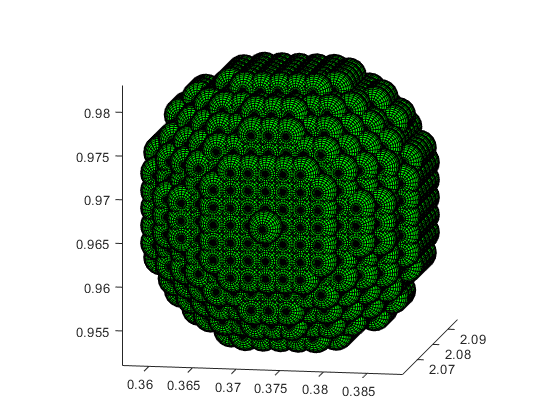

figure
hold on
for i = 1:length(burning_points)
    surf(X*r_burning + burning_points(i, 1), Y*r_burning+ burning_points(i, 2), Z*r_burning + burning_points(i, 3), 'FaceColor', [0 1 0])
end
view([10, 10])
axis equal

### Tumor burning (option 2)

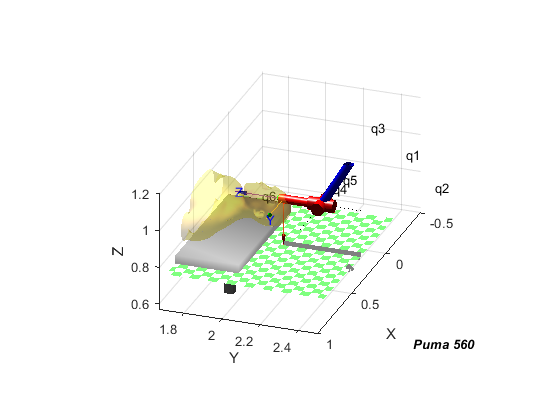

close all

figure
% Display Gurney
patch('Vertices', gurney_vertices, 'Faces', gurney.Gurney_faces, ...
    'FaceColor', [0.52, 0.52, 0.52], ...
    'EdgeColor', 'none', ...
    'FaceLighting', 'gouraud', ...
    'AmbientStrength', 0.15);

% Add a camera light, and tone down the specular highlighting
camlight('headlight');
material('dull');

xlim([0.053 0.692])
ylim([1.667 2.5])
zlim([0.572 1.211])
axis equal

% Display Body
patch('Vertices', human_vertices(:, 1:3), 'Faces', human.F, ...
    'FaceColor', [0.9290, 0.6940, 0.1250], ...
    'FaceAlpha', 0.3, ...
    'EdgeColor', 'none', ...
    'FaceLighting', 'gouraud', ...
    'AmbientStrength', 0.15);
material('dull');
hold on

% Display Skull
% patch('Vertices', skull_vertices(:, 1:3), 'Faces', skull.Fa, ...
%     'FaceColor', [0.82, 0.82, 0.82], ...
%     'FaceAlpha', 0.6, ...
%     'EdgeColor', 'none', ...
%     'FaceLighting', 'gouraud', ...
%     'AmbientStrength', 0.15);
% material('dull');
% axis equal

% Displays the tumor
[X,Z,Y] = sphere(25);
r = 0.016;          % 16mm radius tumor 
surf(X*r + tumor(1), Y*r + tumor(2), Z*r + tumor(3),'FaceColor',[1 0 0])

% Transformation to move the tool appropriately
T_tool = troty(pi/2) * trotx(pi/2);

P_trepanation = [tumor(1), ymaxS-0.005, tumor(3)];

plot3(cir(1,:), cir(2,:), cir(3,:),'r','LineWidth',3);

% Displays the burning points
r_burning = 0.002;
hold on
count = 1;
for i = 1:length(X)
    for j = 1:length(X)
        xb = tumor(1) + X(i, j)*r;
        yb = tumor(2) + Y(i, j)*r;
        zb = tumor(3) + Z(i, j)*r;
  
        ca = P_trepanation(2) - yb;
        co1 = P_trepanation(1) - xb;
        h1 = sqrt(co1^2 + ca^2);
        alphaX = asin(co1/h1);

        co2 = P_trepanation(3) - zb;
        h2 = sqrt(co2^2 + ca^2);
        alphaZ = asin(co2/h2);

        dist = sqrt( (P_trepanation(1) - xb)^2 +  (P_trepanation(2) - yb)^2 + (P_trepanation(3) - zb)^2 );
        
        if count == 1
            Burning_Pose_2(:, :, count) = transl(P_trepanation) * T_tool * troty(-alphaX) * trotx(alphaZ) * transl(0, 0, dist);
            count = count+1;
            xant = xb;
            yant = yb;
            zant = zb;
        else
            distance = sqrt((xb - xant)^2 + (yb - yant)^2 + (zb - zant)^2);
            if distance >= r_burning
                Burning_Pose_2(:, :, count) = transl(P_trepanation) * T_tool * troty(-alphaX) * trotx(alphaZ) * transl(0, 0, dist);
                count = count+1;
                xant = xb;
                yant = yb;
                zant = zb;
            end
        end
    end
end

% Displays the Robot
mdl_puma560
p560.tool = transl(0, 0, 0.2);
p560.base = T_Skull_Ini * transl(xbase, ybase, zbase) * trotz(-pi/2) * troty(pi/2);

Q4 = p560.ikine6s(Burning_Pose_2, 'run');
p560.plot(Q4, 'view', [110 25], 'workspace', [workspaceX, workspaceY, workspaceZ], 'trail', {'color', 'g'}, 'jaxes', 'zoom', 2);

% Creates the video
% p560.plot(Q4, 'view', [110 25], 'workspace', [workspaceX, workspaceY, workspaceZ], 'trail', {'Color', 'g'}, 'zoom', 2, 'movie', 'Puma_burning_task_Op2.mp4');

Displays only the tumor with the burnings

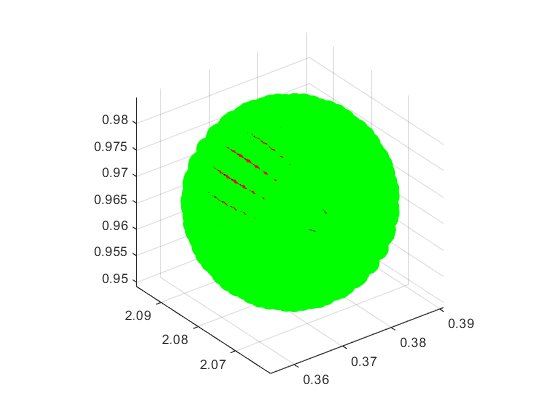

figure
% Displays the tumor
surf(X*r + tumor(1), Y*r + tumor(2), Z*r + tumor(3),'FaceColor',[1 0 0])
axis equal

% Displays the burning points
hold on
count = 1;
for i = 1:length(X)
    for j = 1:length(X)
        xb = tumor(1) + X(i, j)*r;
        yb = tumor(2) + Y(i, j)*r;
        zb = tumor(3) + Z(i, j)*r;
        
        if count == 1
            surf(X*r_burning + xb, Y*r_burning + yb, Z*r_burning + zb, 'EdgeColor', 'none', 'FaceColor', [0 1 0]);
            count = count+1;
            xant = xb;
            yant = yb;
            zant = zb;
        else
            distance = sqrt((xb - xant)^2 + (yb - yant)^2 + (zb - zant)^2);
            if distance >= r_burning
                surf(X*r_burning + xb, Y*r_burning + yb, Z*r_burning + zb, 'EdgeColor', 'none', 'FaceColor', [0 1 0]);
                count = count+1;
                xant = xb;
                yant = yb;
                zant = zb;
            end
        end
    end
end

## *Second approach: ( 40%)*

Modify your code  to repeat the exercise if  the table with the patient is given as happend in the Rosa video.

Do the video again

To know the head relative pose with respect to the Puma Robot ...

*See:  **‘4_Sckeching_Key_ideas_students.mlx’ and ‘5_Skull_pose estimation.mlx’ for inspiration.*

It is desirable to have a pdf report with the following items:

1.- Biopsy trajectory. Plot the profiles of the trajectory and the velocity vector in End Effector Reference Frame

2.- Trepanation. Plot the manipulability index during all time trepanation is been performed. Plot the velocities ellipsoide when the manipulability is lower.

3.- How long it takes the ablation of all the tumor.

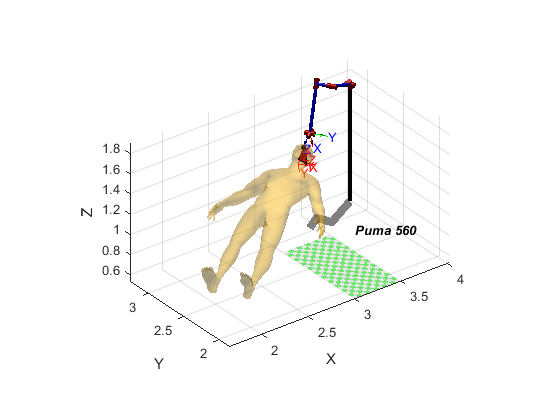

close all

figure
% open('3_Second_approach_Patient_pose.fig')      % Si el Run del mlx no te lo abre haz selección\evaluate
axis([1 4.5 1 4.5 0 2]);

% Display Fiducials
fiducial_1 = [3.2779, 2.8854, 1.2820, 1]';
fiducial_2 = [3.2782, 2.9916, 1.2914, 1]';
fiducial_3 = [3.3259, 2.9595, 1.4216, 1]';

triangle = [fiducial_1(1:3), fiducial_2(1:3), fiducial_3(1:3)];
fill3(triangle(1, :), triangle(2, :), triangle(3, :)', 'r')

hold on
% Skull pose Estimation
AB = (triangle(1:3,1) - triangle(1:3,2)) / norm(triangle(1:3,1) - triangle(1:3,2)); % Vector pointing A 
norm(AB);
CB = (triangle(1:3,3) - triangle(1:3,2)) / norm(triangle(1:3,2) - triangle(1:3,3)); % Vector pointing C
norm(CB);
Z_B = cross(CB, AB) / norm(cross(CB, AB)); % Perpendicular to BA & CB equivalent to â; Z point up
O_B_A = oa2r(AB, Z_B); % AB is the orientation vector (y axis ô) and Z_B is the aproach axis (z axis â). The result ^n is in x axis
O_B_A = [O_B_A(1, :) 0; O_B_A(2, :) 0; O_B_A(3, :) 0; 0 0 0 1];

T_Fiducials_Ini = transl(fiducial_2(1:3)) * O_B_A;
trplot(T_Fiducials_Ini, 'length', 0.1, 'color', 'r')

T_Skull_Ini = T_Fiducials_Ini * T_Skull_Fiducials;
trplot(T_Skull_Ini, 'length', 0.1, 'color', 'r');

T_Body_Ini = T_Skull_Ini * T_Body_Skull;
human_vertices = human_scale .* human.V';  
human_vertices = (T_Body_Ini * [human_vertices; ones(1, length(human.V))])';

% Display the human
patch('Vertices', human_vertices(:, 1:3), 'Faces', human.F, ...
    'FaceColor', [0.9290, 0.6940, 0.1250], ...
    'FaceAlpha', 0.3, ...
    'EdgeColor', 'none', ...
    'FaceLighting', 'gouraud', ...
    'AmbientStrength', 0.15);
% Add effect to the faces
material('dull');

[X,Y,Z] = sphere;
r=0.005;        % 5 mm
surf(X*r + fiducial_1(1), Y*r + fiducial_1(2), Z*r + fiducial_1(3), 'FaceColor', [1 0 0])
surf(X*r + fiducial_2(1), Y*r + fiducial_2(2), Z*r + fiducial_2(3), 'FaceColor', [1 0 0])
surf(X*r + fiducial_3(1), Y*r + fiducial_3(2), Z*r + fiducial_3(3), 'FaceColor', [1 0 0])

hold on
% Scale Skull
skull_scale = 0.0069;
skull_vertices = skull_scale .* skull.Ve';

% Transformation of the position of the skull
skull_vertices = (T_Fiducials_Ini * T_Skull_Fiducials * [skull_vertices; ones(1, length(skull.Ve))])';

% Display Skull
% patch('Vertices', skull_vertices(:, 1:3), 'Faces', skull.Fa, ...
%     'FaceColor', [0.82, 0.82, 0.82], ...
%     'FaceAlpha', 0.6, ...
%     'EdgeColor', 'none', ...
%     'FaceLighting', 'gouraud', ...
%     'AmbientStrength', 0.15);
% material('dull');

% Tumor Pose
hold on 
tumor = [-0.008, -0.030, 0.076*1.4 + 0.06, 1];
tumor = T_Fiducials_Ini * T_Skull_Fiducials * tumor';

% Displays the tumor
[X,Y,Z] = sphere;
r = 0.016;          % 16mm radius tumor 
surf(X*r + tumor(1), Y*r + tumor(2), Z*r + tumor(3),'FaceColor',[1 0 0])

% Displays the robot (without any tool)
hold on
mdl_puma560
xbase = T_Tumor_Skull(1) + p560.links(3).d;
zbase = T_Tumor_Skull(3) + sqrt(2) * p560.links(2).a + 0.15;
ybase = T_Tumor_Skull(2) - r;

p560.base = T_Skull_Ini * transl(xbase, ybase, zbase) * trotz(-pi/2) * troty(pi/2);
workspaceX = [T_Skull_Ini(1, 4) + xbase - 0.3, T_Skull_Ini(1, 4) + xbase + 0.2];
workspaceY = [T_Skull_Ini(2, 4) + ybase - 1, T_Skull_Ini(2, 4) + ybase];
workspaceZ = [T_Skull_Ini(3, 4) - 0.8, T_Skull_Ini(3, 4) + 0.1];
p560.plot(qn, 'zoom', 2.5, 'workspace', [workspaceX, workspaceY, workspaceZ]);

axis equal

### Biopsy 2nd aproach

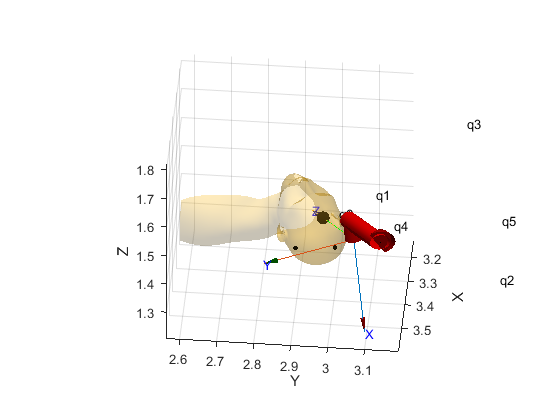

close all

% Display the human
patch('Vertices', human_vertices(:, 1:3), 'Faces', human.F, ...
    'FaceColor', [0.9290, 0.6940, 0.1250], ...
    'FaceAlpha', 0.3, ...
    'EdgeColor', 'none', ...
    'FaceLighting', 'gouraud', ...
    'AmbientStrength', 0.15);
% Add effect to the faces
material('dull');

hold on
r=0.005;        % 5 mm
surf(X*r + fiducial_1(1), Y*r + fiducial_1(2), Z*r + fiducial_1(3), 'FaceColor', [1 0 0])
surf(X*r + fiducial_2(1), Y*r + fiducial_2(2), Z*r + fiducial_2(3), 'FaceColor', [1 0 0])
surf(X*r + fiducial_3(1), Y*r + fiducial_3(2), Z*r + fiducial_3(3), 'FaceColor', [1 0 0])

r = 0.016;          % 16mm radius tumor 
surf(X*r + tumor(1), Y*r + tumor(2), Z*r + tumor(3),'FaceColor',[1 0 0])

% Transformation to move the tool appropriately
T_tool = troty(pi) * trotz(pi/2);

Tumor_center = T_Skull_Ini * transl(T_Tumor_Skull(1:3));

xlim([3.135 3.597])
ylim([2.564 3.192])
zlim([1.207 1.824])

n = 200;
% Go inside the skull
for i = 1:n
    Biopsy_Pose_Second_approach(:, :, i) = Tumor_center * transl(0, 0, 0.2 * ((n - i)/n)) * T_tool;
end

% Stay inside the skull
for i = 1:n/4
    Biopsy_Pose_Second_approach(:, :, i+n) = Tumor_center * T_tool;
end

% Go outside the skull
for i = 1:n
    Biopsy_Pose_Second_approach(:, :, i+n+n/4) = Tumor_center * transl(0, 0, 0.2 * (1 - ((n - i)/n))) * T_tool;
end

% Display Robot
mdl_puma560
p560.tool = transl(0.05, 0, 0.25);
p560.base = T_Skull_Ini * transl(xbase, ybase, zbase) * trotz(-pi/2) * troty(pi/2);
Q5 = p560.ikine6s(Biopsy_Pose_Second_approach, 'run');
p560.plot(Q5, 'view', [95 40], 'workspace', [workspaceX, workspaceY, workspaceZ], 'trail', {'color', 'g'}, 'jaxes', 'zoom', 2);

% Creates the video
% p560.plot(Q5, 'view', [95 40], 'workspace', [workspaceX, workspaceY, workspaceZ], 'trail', {'color', 'g'}, 'zoom', 2, 'movie', 'Puma_biopsy_task_Second_approach.mp4');

### Trepanation 2nd aproach

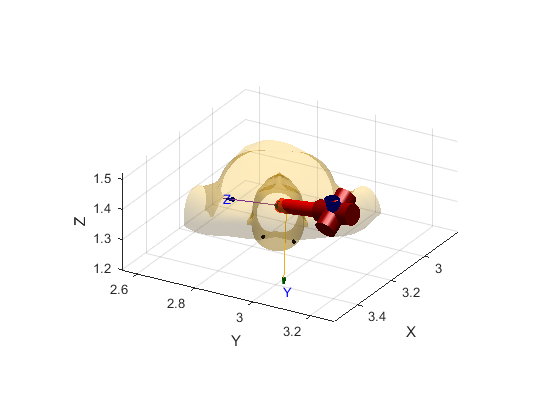

close all

figure

% Display the human
patch('Vertices', human_vertices(:, 1:3), 'Faces', human.F, ...
    'FaceColor', [0.9290, 0.6940, 0.1250], ...
    'FaceAlpha', 0.3, ...
    'EdgeColor', 'none', ...
    'FaceLighting', 'gouraud', ...
    'AmbientStrength', 0.15);
% Add effect to the faces
material('dull');

xlim([2.804 3.539])
ylim([2.550 3.284])
zlim([1.199 1.522])

hold on
r=0.005;        % 5 mm
surf(X*r + fiducial_1(1), Y*r + fiducial_1(2), Z*r + fiducial_1(3), 'FaceColor', [1 0 0])
surf(X*r + fiducial_2(1), Y*r + fiducial_2(2), Z*r + fiducial_2(3), 'FaceColor', [1 0 0])
surf(X*r + fiducial_3(1), Y*r + fiducial_3(2), Z*r + fiducial_3(3), 'FaceColor', [1 0 0])

r = 0.016;          % 16mm radius tumor 
surf(X*r + tumor(1), Y*r + tumor(2), Z*r + tumor(3),'FaceColor',[1 0 0])

n = 100;
radius = r;

load('Cone.mat')

% Gets the cone transformation
xminC = min(fvc.vertices(:, 1));
xmaxC = max(fvc.vertices(:, 1));
cone_scale = r/((xmaxC - xminC)/2);
cone_vertices = cone_scale .* fvc.vertices';

cone_pose = Tumor_center * transl(0, 0, 0.02) * trotx(pi); 
cone_vertices = (cone_pose * [cone_vertices; ones(1, length(cone_vertices))])';

% Displays the Cone
patch('Vertices', cone_vertices(:, 1:3), 'Faces', fvc.faces, ...
    'FaceVertexCData', hsv(6), ...
    'FaceColor', 'b', ...
    'FaceAlpha', 0.3);

% Display the trepanation perimeter
T_tool = troty(pi/4) * trotx(pi);
Trep_pose = cone_pose * troty(182 * pi/180) * transl(0, 0, -0.001);
for i=1:n
    Trepanation_Pose_Second_Approach(:,:,i)= Trep_pose*trotz(2*pi*i/n)*transl(radius-0.001, 0, 0) * T_tool;
end

cir=transl(Trepanation_Pose_Second_Approach)';
hold on
plot3(cir(1,:), cir(2,:), cir(3,:),'r','LineWidth',3);

% Display Robot
mdl_puma560
p560.tool = transl(0, 0, 0.2);
p560.base = T_Skull_Ini * transl(xbase, ybase, zbase) * trotz(-pi/2) * troty(pi/2);
Q6 = p560.ikine6s(Trepanation_Pose_Second_Approach, 'run');
p560.plot(Q6, 'view', [-240 25], 'workspace', [workspaceX, workspaceY, workspaceZ], 'trail', {'color', 'g'}, 'zoom', 2);

% Creates the video
% p560.plot(Q6, 'view', [-240 25], 'workspace', [workspaceX, workspaceY, workspaceZ], 'trail', {'color', 'g'}, 'zoom', 2, 'movie', 'Puma_trepanation_task_Second_approach.mp4');

### Manipulability index of trepanation

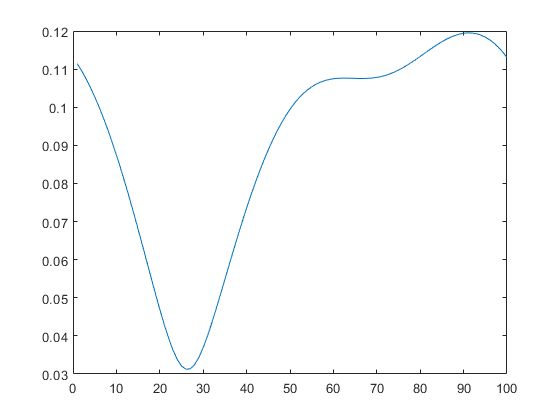

close all

manipulability = p560.maniplty(Q6);
plot (manipulability);

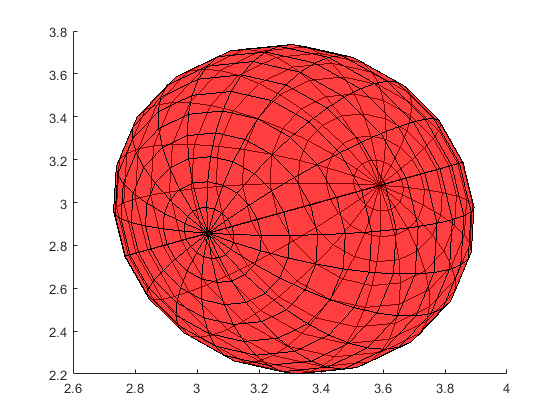

close all

p560.vellipse(Q6(26,:));

### Burning 2nd aproach

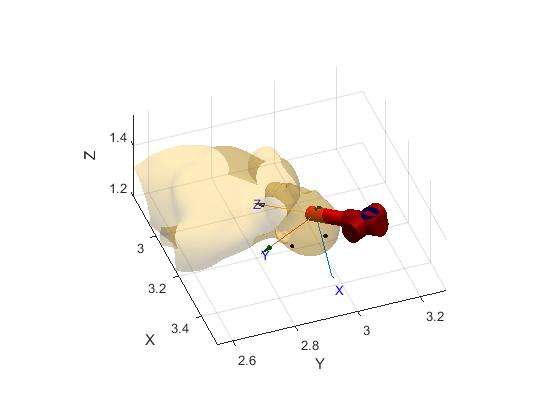

close all

figure

% Display the human
patch('Vertices', human_vertices(:, 1:3), 'Faces', human.F, ...
    'FaceColor', [0.9290, 0.6940, 0.1250], ...
    'FaceAlpha', 0.3, ...
    'EdgeColor', 'none', ...
    'FaceLighting', 'gouraud', ...
    'AmbientStrength', 0.15);
% Add effect to the faces
material('dull');

xlim([2.804 3.539])
ylim([2.550 3.284])
zlim([1.199 1.522])

hold on
r=0.005;        % 5 mm
surf(X*r + fiducial_1(1), Y*r + fiducial_1(2), Z*r + fiducial_1(3), 'FaceColor', [1 0 0])
surf(X*r + fiducial_2(1), Y*r + fiducial_2(2), Z*r + fiducial_2(3), 'FaceColor', [1 0 0])
surf(X*r + fiducial_3(1), Y*r + fiducial_3(2), Z*r + fiducial_3(3), 'FaceColor', [1 0 0])

r = 0.016;          % 16mm radius tumor 
surf(X*r + tumor(1), Y*r + tumor(2), Z*r + tumor(3),'FaceColor',[1 0 0])

% Transformation to move the tool appropriately
T_tool = troty(pi/2) * trotz(pi/2) * trotx(pi/2);

% Get burning points
center = tumor(1:3)';
r_burning = 0.002;
queue = center;
burning_points = center;
visited = center;

adjacent = [     r_burning,          0,          0;
                -r_burning,          0,          0;
                         0,  r_burning,          0;
                         0, -r_burning,          0;
                         0,          0,  r_burning;
                         0,          0, -r_burning];
count = 1;
while isempty(queue) == 0
    act = queue(1, :);
    m = size(queue);
    queue = queue(2:m(1), :);
    
    for k = 1:length(adjacent)
        pos = act + adjacent(k, :);
        m = size(visited);

        vis = false;
        for t = 1:m(1)
            if visited(t, 1) == pos(1) && visited(t, 2) == pos(2) && visited(t, 3) == pos(3)
                vis = true;
                break;
            end
        end
        
        if ~vis
            distance = sqrt((center(1) - pos(1))^2 + (center(2) - pos(2))^2 + (center(3) - pos(3))^2);
            if distance <= r
                queue = [queue; pos];
                burning_points = [burning_points; pos];
                visited = [visited; pos];
            end
        end
    end
end

for i = 1:length(burning_points)
    Burning_Pose_Second_Approach(:, :, i) = T_Skull_Ini;
    Burning_Pose_Second_Approach(1, 4, i) = burning_points(i, 1);
    Burning_Pose_Second_Approach(2, 4, i) = burning_points(i, 2);
    Burning_Pose_Second_Approach(3, 4, i) = burning_points(i, 3);
    Burning_Pose_Second_Approach(:, :, i) = Burning_Pose_Second_Approach(:, :, i) * T_tool;
end

% Display Robot
mdl_puma560
p560.tool = transl(0, 0, 0.2);
p560.base = T_Skull_Ini * transl(xbase, ybase, zbase) * trotz(-pi/2) * troty(pi/2);
Q7 = p560.ikine6s(Burning_Pose_Second_Approach, 'run');
p560.plot(Q7, 'view', [-290 40], 'workspace', [workspaceX, workspaceY, workspaceZ], 'trail', {'color', 'g'}, 'zoom', 2);

% Creates the video
% p560.plot(Q7, 'view', [-290 40], 'workspace', [workspaceX, workspaceY, workspaceZ], 'trail', {'color', 'g'}, 'zoom', 2, 'movie', 'Puma_burning_task_Second_approach.mp4');